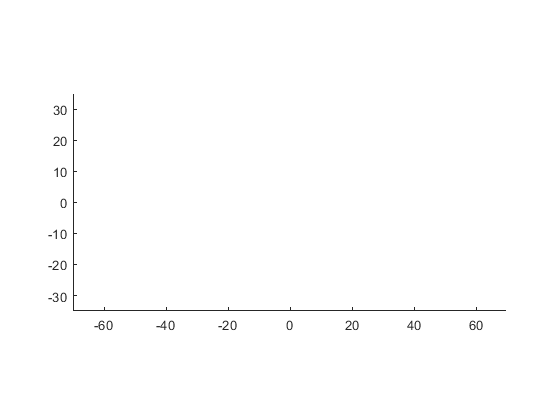

% Name of the file
folder = '../dpm/';
d0 = dir([folder, 'dpm_data_*_step1.dpm']);
d0names = string({d0.name});

selectedFile = d0names(29);

d = dir(join([folder, selectedFile], ''));
name = d.name;
s = split(d(1).name, '_');
s{end} = [s{end}(1:4), '*', s{end}(end-3:end)];
f = join(s, '_');
filename = f{1};

strings = split(filename, '_');
ch_found = 0;
cw_found = 0;
for k = 1:length(strings)
    if startsWith(strings{k},'cw')
        cw = str2double(strings{k}(3:end));
        cw_found = 1;
    end

    if startsWith(strings{k},'ch')
        ch = str2double(strings{k}(3:end));
        ch_found = 1;
    end
end

if ~ch_found || ~cw_found
    error('Poorly formed filename string (does not contain cw and ch');
end

d = dir([folder, filename]);
numberOfSteps = length(d);
f = waitbar(0, 'Starting');
for i = 1:numberOfSteps
    [stepNumberOutlet, outletDataTable] = processDataFromStepFile([d(i).folder, '\', d(i).name]);
    [stepNumberInlet, inletDataTable] = processDataFromStepFile([d(i).folder, '\dpm_inlet', d(i).name(4:end)]);

    outletData{stepNumberOutlet} = sortrows(outletDataTable, 'name');
    inletData{stepNumberInlet} = sortrows(inletDataTable, 'name');

    waitbar(i/numberOfSteps, f, sprintf('Loading Steps: %d %%', floor(i/numberOfSteps*100)));
end
close(f);

close all; clc; figure;
axis equal;
xlim([-cw/2, cw/2]);
ylim([-ch/2, ch/2]);


ax = gca;
AR = get(gca, 'dataaspectratio');
if ~isequal(AR(1:2), [1 1])
  error('Units are not equal on X and Y, cannot create marker size that is one unit on both');
end
oldunits = get(ax, 'Units');
set(ax, 'Units', 'points');
pos = get(ax, 'Position');    %[X Y width height]
set(ax, 'Units', oldunits');
XL = xlim(ax);
points_per_unit = pos(3) / (XL(2) - XL(1));
marker_size = points_per_unit .^2 * pi / 4;   



## surface

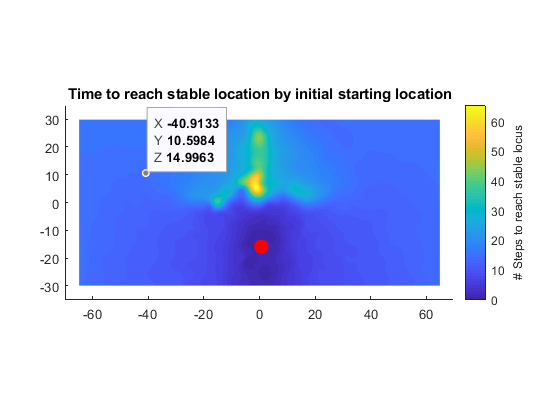

close all;
figure;
d = [];
sp = [];
nsteps = length(inletData);
nparticles = length(inletData{1}.name);
% loop over the particles
f = waitbar(0, 'Starting Particle Tracking');
for i = 1:nparticles
    sp(i,1:2) = [inletData{1}.z(i), inletData{1}.y(i)] * 1e6; % start point
    % find ending position of each particle
    epz = outletData{end}.z(i);
    epy = outletData{end}.y(i);

    % track how long it takes to get within a certain distance of the
    % ending position
    % loop over the steps for each particle i
    particleID = inletData{1}.name(i);
    
    for k = 1:nsteps-1
        % the inlet name and outlet name of a step correspond
        particleRow = find(outletData{k}.name == particleID,1,'first');
        particlePosition = [outletData{k}.z(particleRow), outletData{k}.y(particleRow)];
        
        d(i,k) = sqrt((particlePosition(1)-epz)^2 + (particlePosition(2)-epy)^2) * 1e6;
    
        % find the new particle id for the next step
        % the outlet position in one step and the inlet position in the next step *should* correspond
        outletInletDistance = sqrt((inletData{k+1}.z - particlePosition(1)).^2 + (inletData{k+1}.y - particlePosition(2)).^2);
        particleRow = find(outletInletDistance == min(outletInletDistance),1,'first');
        particleID = inletData{k+1}.name(particleRow);
    end

    % check if the particle ever made it to the ending point? Wait maybe
    % the particles got mixed up?
    if (isempty(find(d(i,:)<5,1,'first')))
        sp(i, 3) = NaN; % maybe nan?
    else
        sp(i, 3) = find(d(i,:)<5,1,'first');
    end
    
    waitbar(i/nparticles, f, sprintf('Tracking Particles: %d %%', floor(i/nparticles*100)));
end
close(f);

x = sp(~isnan(sp(:,3)),1);
y = sp(~isnan(sp(:,3)),2);
z = sp(~isnan(sp(:,3)),3);
xlin = linspace(min(x), max(x), 120);
ylin = linspace(min(y), max(y), 60);
[X,Y] = meshgrid(xlin, ylin);
% Z = griddata(x,y,z,X,Y,'natural');
% Z = griddata(x,y,z,X,Y,'cubic');
Z = griddata(x,y,z,X,Y,'v4');
surf(X,Y,Z)
shading interp;
grid off
c = colorbar;
c.Label.String = '# Steps to reach stable locus';
hold on;
% draw an ellipse of the standard deviation bounds
% Ellipse parameters
center_x = mean(outletData{end}.z) * 1e6;
center_y = mean(outletData{end}.y) * 1e6;
plot3(center_x, center_y, max(z)+1,'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
title('Time to reach stable location by initial starting location')
view([0 90.0])

axis equal;
xlim([-cw/2, cw/2]);
ylim([-ch/2, ch/2]);


figure;

## display

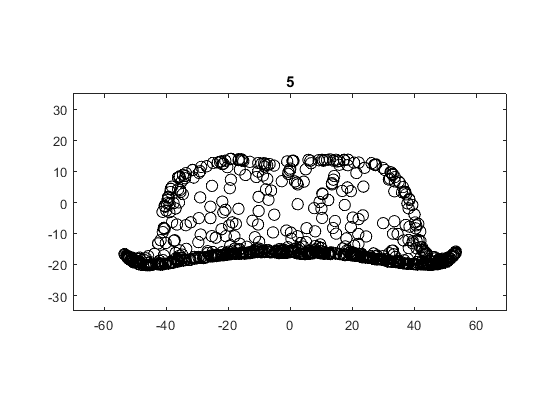

displayStep =5;
% Display the table
plot(outletData{displayStep}.z * 1e6, outletData{displayStep}.y * 1e6, 'ko', 'MarkerSize', 2*marker_size);
hold on;
% for i = 1:length(inletData{displayStep}.z)
%     id = inletData{displayStep};
%     od = outletData{displayStep};
% 
%     plot([id.z(i), od.z(i)] * 1e6, ...
%          [id.y(i), od.y(i)] * 1e6, ...
%         'b');
% end

hold off;

% draw an ellipse of the standard deviation bounds
% Ellipse parameters
center_x = mean(outletData{displayStep}.z) * 1e6;
center_y = mean(outletData{displayStep}.y) * 1e6;
width = 2 * 3 * std(outletData{displayStep}.z) * 1e6;  % Semi-major axis (horizontal axis length)
height = 2 * 3 * std(outletData{displayStep}.y) * 1e6;   % Semi-minor axis (vertical axis length)

% Draw the ellipse using the rectangle function
% rectangle('Position', [center_x - width/2, center_y - height/2, width, height], ...
%           'Curvature', [1, 1], ...
%           'EdgeColor', 'r', ...
%           'LineWidth', 2);

axis equal;
xlim([-cw/2, cw/2]);
ylim([-ch/2, ch/2]);
title(displayStep);

## test

[dataTable] = processDataFromOutletFile('C:\Users\williamstoy\Documents\GitHub\microfluidics-y-combiner\microfluidics-y-combiner_files\dp0\FFF\Fluent\outlet.dpm');


## functions

function [dataTable] = processDataFromOutletFile(fname)
% Open the file
    d = dir(fname);
    folder = d(1).folder;
    filename = d(1).name;

    fid = fopen([folder, '\', filename], 'r');
    
    % Read the file line by line and store the data
    data = [];
    while ~feof(fid)
        line = fgetl(fid);
        
        % Check if line starts with '((' indicating data
        if startsWith(line, '((')
            
            % Split the line based on spaces
            value_texts = strsplit(line(4:end-1), ' ');
            value_texts{12} = value_texts{12}(1:end-1); % remove the trailing ')'
            
            id_data = strsplit(value_texts{end}, ':');
            value_texts{end} = id_data{2};

            values = str2double(value_texts);
            
            % Append to data
            data = [data; values];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Convert the array data to a table
    columnNames = {'x', 'y', 'z', 'u', 'v', 'w', 'diameter', 't', 'mass-flow', 'mass', 'frequency', 'time', 'name'};
    dataTable = array2table(data, 'VariableNames', matlab.lang.makeValidName(columnNames));
end

function [stepNumber, dataTable] = processDataFromStepFile(fname)
% Open the file
    d = dir(fname);
    folder = d(1).folder;
    filename = d(1).name;

    fid = fopen([folder, '\', filename], 'r');

    % get the step name from the file
    % Use regular expression to match the pattern and extract the step number
    pattern = 'step(\d+)\.dpm';
    tokens = regexp(filename, pattern, 'tokens');
    
    % Convert the extracted number (stored in tokens{1}{1}) to double
    if ~isempty(tokens)
        stepNumber = str2double(tokens{1}{1});
        %disp(['Step Number: ', num2str(stepNumber)]);
    else
        error('Pattern not found in filename.');
    end
    
    % Read the file line by line and store the data
    data = [];
    while ~feof(fid)
        line = fgetl(fid);
        
        % Check if line starts with '((' indicating data
        if startsWith(line, '((')
            
            % Split the line based on spaces
            value_texts = strsplit(line(4:end-1), ' ');
            value_texts{12} = value_texts{12}(1:end-1); % remove the trailing ')'
            
            id_data = strsplit(value_texts{end}, ':');
            value_texts{end} = id_data{2};

            values = str2double(value_texts);
            
            % Append to data
            data = [data; values];
        end
    end
    
    % Close the file
    fclose(fid);
    
    % Convert the array data to a table
    columnNames = {'x', 'y', 'z', 'u', 'v', 'w', 'diameter', 't', 'mass-flow', 'mass', 'frequency', 'time', 'name'};
    dataTable = array2table(data, 'VariableNames', matlab.lang.makeValidName(columnNames));
end